% Offline Classification
clear

% Define labels for rock, paper, and scissors
label_rps = string(["rock","paper","scissors"]);

% Specify the file(s) to load
% filesToLoad = {"training_feature_table.mat", "testing_feature_table.mat"};
filesToLoad = {"final_data.mat"};

% Temporarily load the feature data to get selected features
load(filesToLoad{1})
feature_table.Properties.VariableNames

ans = 1×28 cell array
    {'var_Ch1'}    {'var_Ch2'}    {'var_Ch3'}    {'var_Ch4'}    {'rms_Ch1'}    {'rms_Ch2'}    {'rms_Ch3'}    {'rms_Ch4'}    {'mav_Ch1'}    {'mav_Ch2'}    {'mav_Ch3'}    {'mav_Ch4'}    {'wl_Ch1'}    {'wl_Ch2'}    {'wl_Ch3'}    {'wl_Ch4'}    {'iav_Ch1'}    {'iav_Ch2'}    {'iav_Ch3'}    {'iav_Ch4'}    {'ld_Ch1'}    {'ld_Ch2'}    {'ld_Ch3'}    {'ld_Ch4'}    {'zc_Ch1'}    {'zc_Ch2'}    {'zc_Ch3'}    {'zc_Ch4'}



% Define the selected features
% selected_features = 1:size(finalFeatureTable,2); % Select all features
selected_features = [9 10 11 12 13 14 15 16]; % Select specific features

% Define the features to include
includedFeatures = {'var', 'rms', 'mav', 'wl', 'iav', 'ld', 'zc'};

% Clear temporary variables
clearvars feature_table gesturelist

% Load feature data and organize into X and y matrices
[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);

Loading prior training-test partition


% Build Classifier + K-Fold Cross-Validation
% Perform k-fold cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Initialize vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all folds
for fold = 1:KFolds
    % Assign data for training and validation in the current fold
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train, kfold_partial_data_y_train);

    % Make predictions with the temporary classifier
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

% Calculate cross-validation metrics
[validation_accuracy] = calculateMetrics(y_train, validation_predictions);

% Build a classifier on all of the training data
% Create a classifier
currentClassifier = createClassifier(X_train, y_train);

% Use classifier to predict on training data (resubstitution)
y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy, train_fone, train_confusion, train_tpr] = calculateMetrics(y_train, y_train_predictions);

% Use classifier to predict on test data
y_test_predictions = currentClassifier.predict(X_test);
[test_accuracy, test_fone, test_confusion, test_tpr] = calculateMetrics(y_test, y_test_predictions);


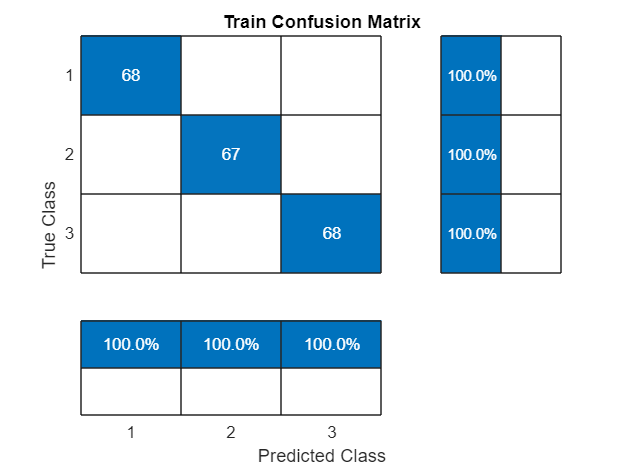

% Display confusion matrices
confusionchart(train_confusion, unique(y_train), 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized', 'Title', 'Train Confusion Matrix');

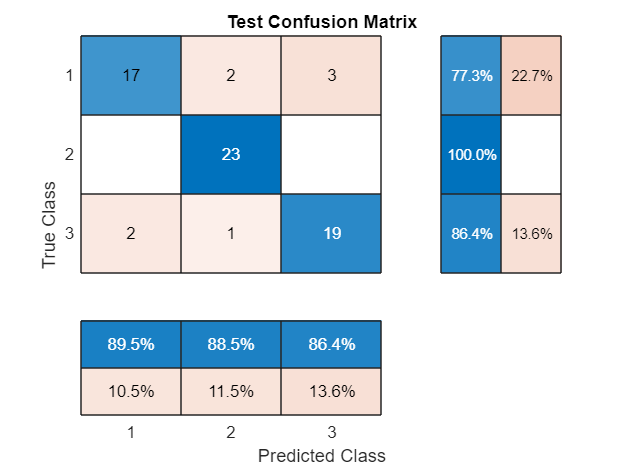

confusionchart(test_confusion, unique(y_test), 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized', 'Title', 'Test Confusion Matrix');


% Display results and save the current classifier
Type = ["Accuracy"; "Average F1"; "Average TPR"];
Train = [train_accuracy; train_fone; train_tpr];
Test = [test_accuracy; test_fone; test_tpr];
% Live = [0.4; "N/A"; "N/A"]
results = table(Train, Test, 'RowNames', Type);
disp(results);

                   Train     Test  
                   _____    _______

    Accuracy         1       0.8806
    Average F1       1      0.87723
    Average TPR      1      0.87879



save("currentClassifier.mat", "currentClassifier", "selected_features", "includedFeatures");

% Helper Functions

% Function to create X_train, y_train, X_test, and y_test

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)
    % Check the number of files to load
    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else
        error("Wrong number of files to load.")
    end

    % Load the training data
    load(filesToLoad{1});

    % If separate test data
    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:, selected_features);
        y_train = gesturelist;

        % Load the test data
        load(filesToLoad{2});

        % Put the test data into X and y
        X_test = feature_table(:, selected_features);
        y_test = gesturelist;
    
    % If split the train / test data from one file
    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;

        try 
            % Load a saved partition from last time (if it exists)
            load("lastCVpartition.mat")
            disp("Loading prior training-test partition")

            % Check if the loaded partition matches the current data
            if cvtt.NumObservations ~= length(gesturelist) || abs(cvtt.TestSize/cvtt.NumObservations - holdout_proportion_test) > 0.1
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                cvtt = cvpartition(gesturelist, "HoldOut", holdout_proportion_test);
            end
        catch
            % Create a new partition if no saved partition exists
            cvtt = cvpartition(gesturelist, "HoldOut", holdout_proportion_test);
            save("./lastCVpartition.mat", "cvtt");
            disp('Making new training-test partition')
        end
        
        % Train data
        X_train = feature_table(training(cvtt), selected_features);
        y_train = gesturelist(training(cvtt));

        % Test data
        X_test = feature_table(test(cvtt), selected_features);
        y_test = gesturelist(test(cvtt));
    end
end

% Function to build a model based on data
function [theClassifier] = createClassifier(dataIn, labelsIn)
    % Various models can be used here for 3 classes
    % Uncomment one of the following options or add more details/parameters
    % theClassifier = fitcdiscr(dataIn, labelsIn); % Linear discriminant analysis
    % theClassifier = fitctree(dataIn, labelsIn); % Decision tree
    theClassifier = fitcensemble(dataIn, labelsIn, 'Method', 'Bag', 'NumLearningCycles', 100); % Ensemble of Decision Trees
    % theClassifier = fitcknn(dataIn, labelsIn, "NumNeighbors", 3); % K-Nearest Neighbors
    % theClassifier = fitcnb(dataIn, labelsIn); % Naive Bayes
end

% Function to calculate key metrics
function [accuracy, fone_score, confusion_matrix, average_tpr] = calculateMetrics(true_labels, predicted_labels)
    % Calculate accuracy
    accuracy = sum(true_labels == predicted_labels) / length(true_labels);

    % Determine the number of classes
    num_classes = max(true_labels);

    % Initialize arrays for F1 scores and true positive rates (TPR)
    f1_scores = zeros(num_classes, 1);
    tpr = zeros(num_classes, 1);

    % Loop through each class
    for c = 1:num_classes
        % Calculate true positives (TP), false positives (FP), and false negatives (FN)
        TP = sum(true_labels == c & predicted_labels == c);
        FP = sum(true_labels ~= c & predicted_labels == c);
        FN = sum(true_labels == c & predicted_labels ~= c);

        % Calculate precision and recall
        precision = TP / (TP + FP);
        recall = TP / (TP + FN);

        % Calculate F1 score and true positive rate
        f1_scores(c) = 2 * (precision * recall) / (precision + recall);
        tpr(c) = recall;
    end

    % Calculate the average F1 score and overall true positive rate
    fone_score = mean(f1_scores);
    confusion_matrix = confusionmat(true_labels, predicted_labels);
    average_tpr = mean(tpr);
end